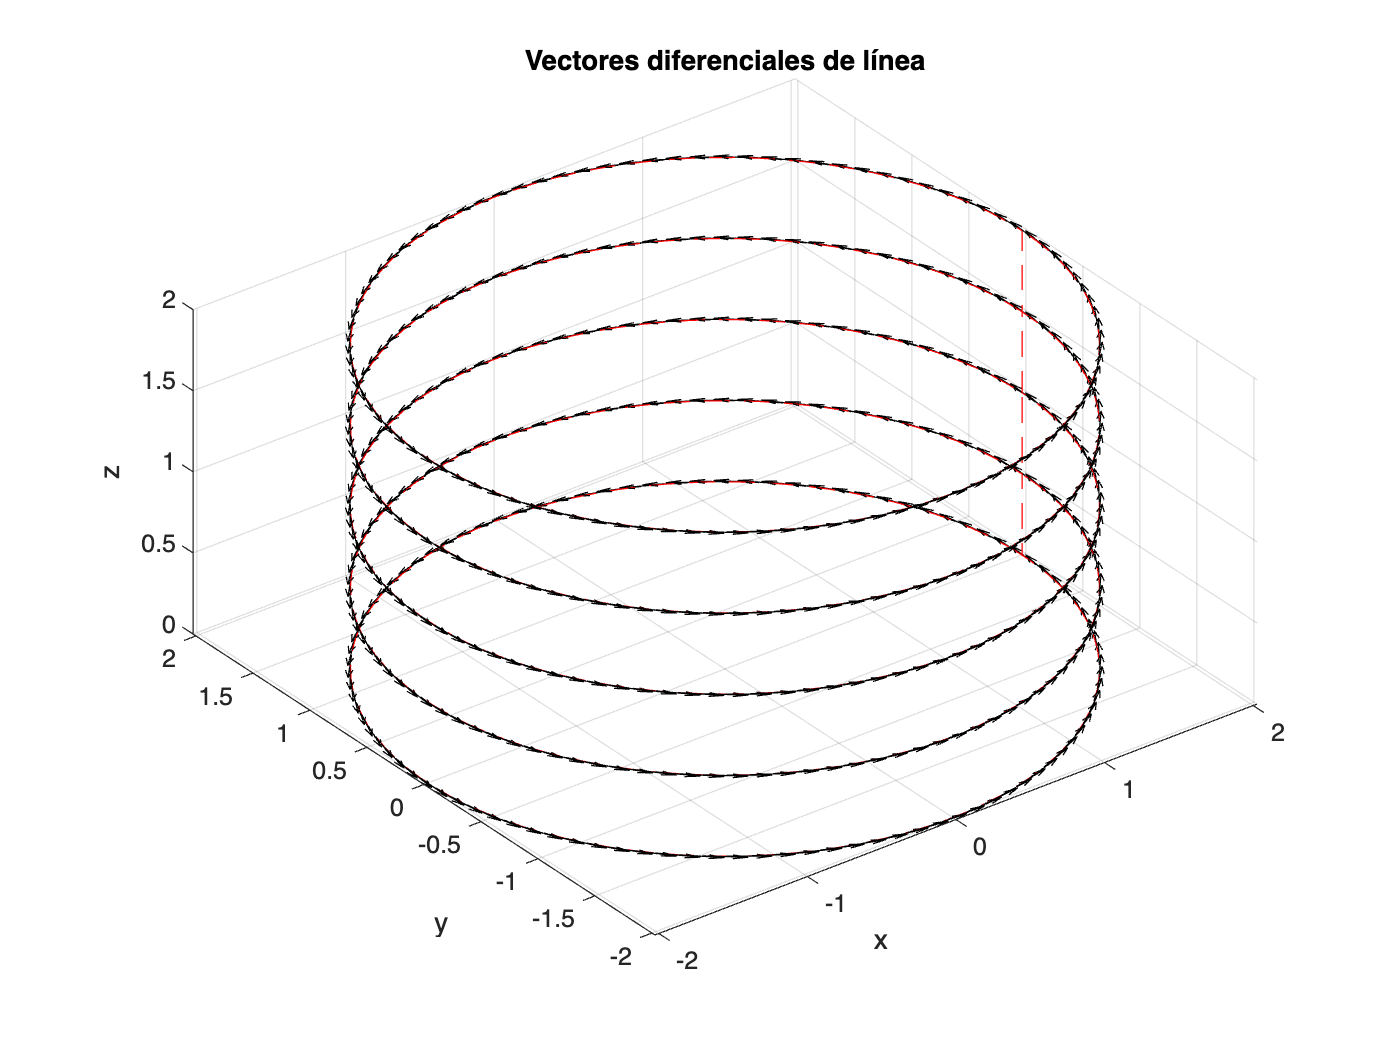

n = 5;       % Número de vueltas
r = 2;       % Radio de la espira
dz = 0.5;    % Separación entre vueltas
N = 100;     % Puntos por vuelta

theta = linspace(0, 2*pi, N);
difang = (2*pi)/N;

x_all = [];
y_all = [];
z_all = [];
theta_all = [];

for k = 0:n-1
    x = r * cos(theta);
    y = r * sin(theta);
    z = dz * k * ones(size(theta)); 

    x_all = [x_all, x];
    y_all = [y_all, y];
    z_all = [z_all, z];
    theta_all = [theta_all, theta];
end

dx = -r * sin(theta_all) * difang;
dy =  r * cos(theta_all) * difang;
dzl = zeros(size(dx));

figure;
plot3(x_all, y_all, z_all, 'r--'), hold on
quiver3(x_all, y_all, z_all, dx, dy, dzl, 'k')
xlabel('x'), ylabel('y'), zlabel('z')
title('Vectores diferenciales de línea')
axis equal, grid on

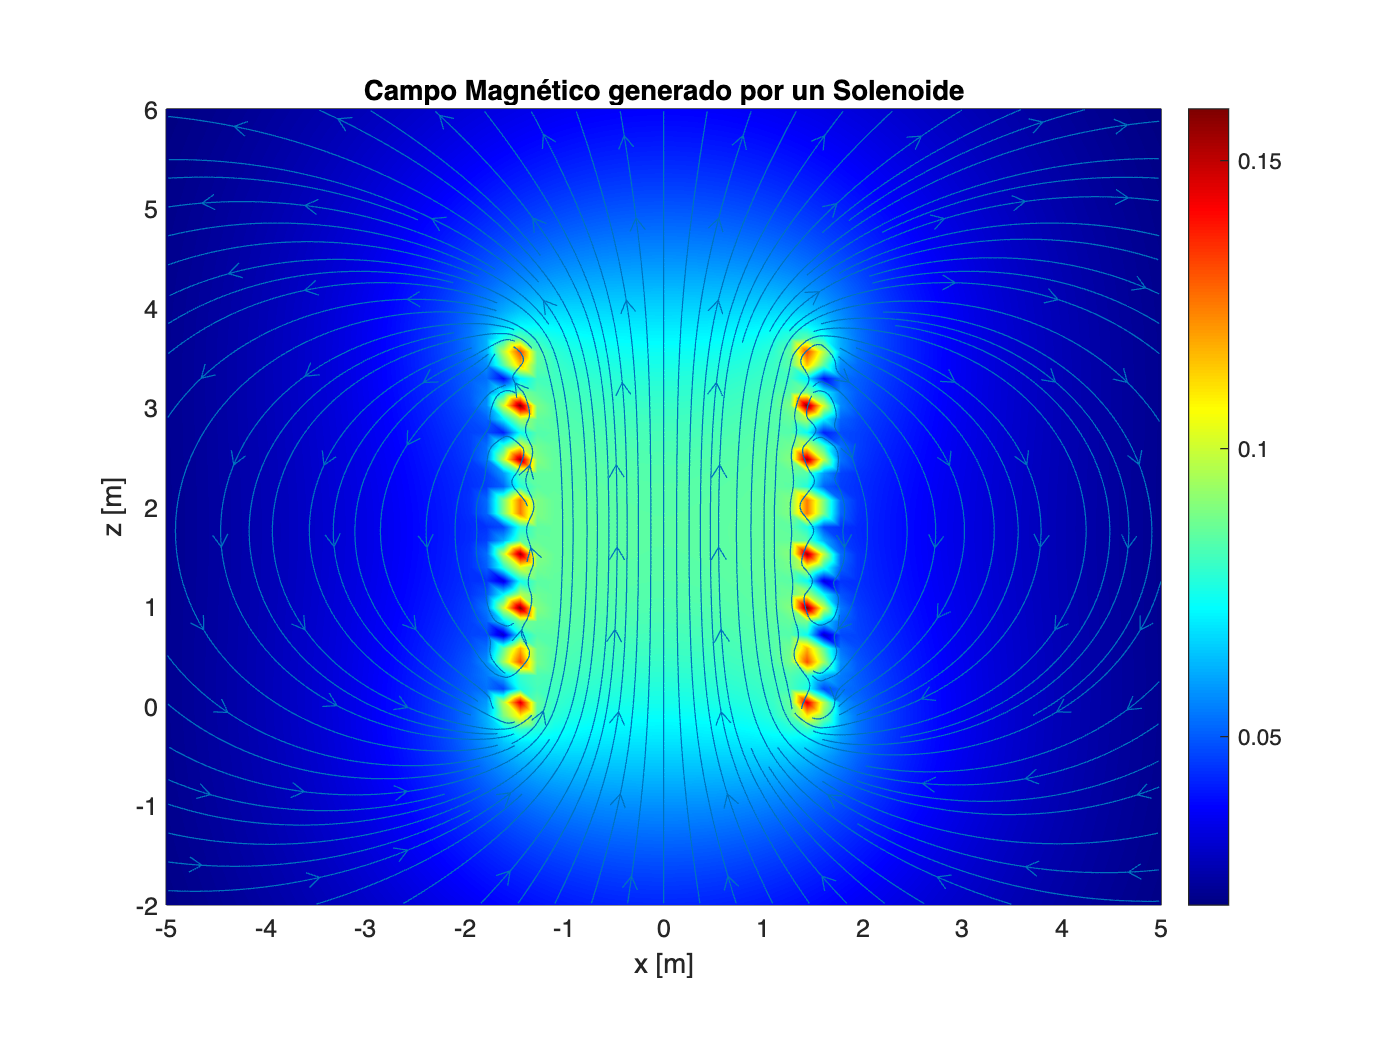

nl = 8;                  % Número de vueltas
N = 20;                  % Puntos por vuelta
R = 1.5;                 % Radio del solenoide
sz = 0.5;                % Separación entre vueltas
I = 300;                 % Corriente
mo = 4*pi*1e-7;          % Permeabilidad del vacío
km = mo * I / (4*pi);    % Constante de Biot-Savart

lx = 60; Lz = 60;
x = linspace(-5, 5, lx);
y = 0;
z = linspace(-2, nl*sz + 2, Lz);
[X, Z] = meshgrid(x, z);

Bx = zeros(Lz, lx);
Bz = zeros(Lz, lx);

for i = 1:lx
    for k = 1:Lz
        B = [0, 0, 0];
        for l = 1:nl*N
            vuelta = fix((l - 1) / N);
            punto = l - vuelta*N;
            theta = 2*pi*(punto - 1)/N;
            rc = [R*cos(theta), R*sin(theta), vuelta*sz];
            dtheta = 2*pi/N;
            dl = [-R*sin(theta)*dtheta, R*cos(theta)*dtheta, 0];
            rp = [x(i), y, z(k)];
            r = rp - rc;
            r_norm = norm(r);
            if r_norm ~= 0
                dB = km * cross(dl, r) / (r_norm^3);
                B = B + dB;
            end
        end
        Bx(k, i) = B(1);
        Bz(k, i) = B(3);
    end
end

Bmag = sqrt(Bx.^2 + Bz.^2);
figure;
pcolor(x, z, Bmag.^(1/3)); shading interp;
colormap(jet); colorbar;
hold on;
streamslice(x, z, Bx, Bz, 2);
xlabel('x [m]'); ylabel('z [m]');
title('Campo Magnético generado por un Solenoide');
axis equal tight;

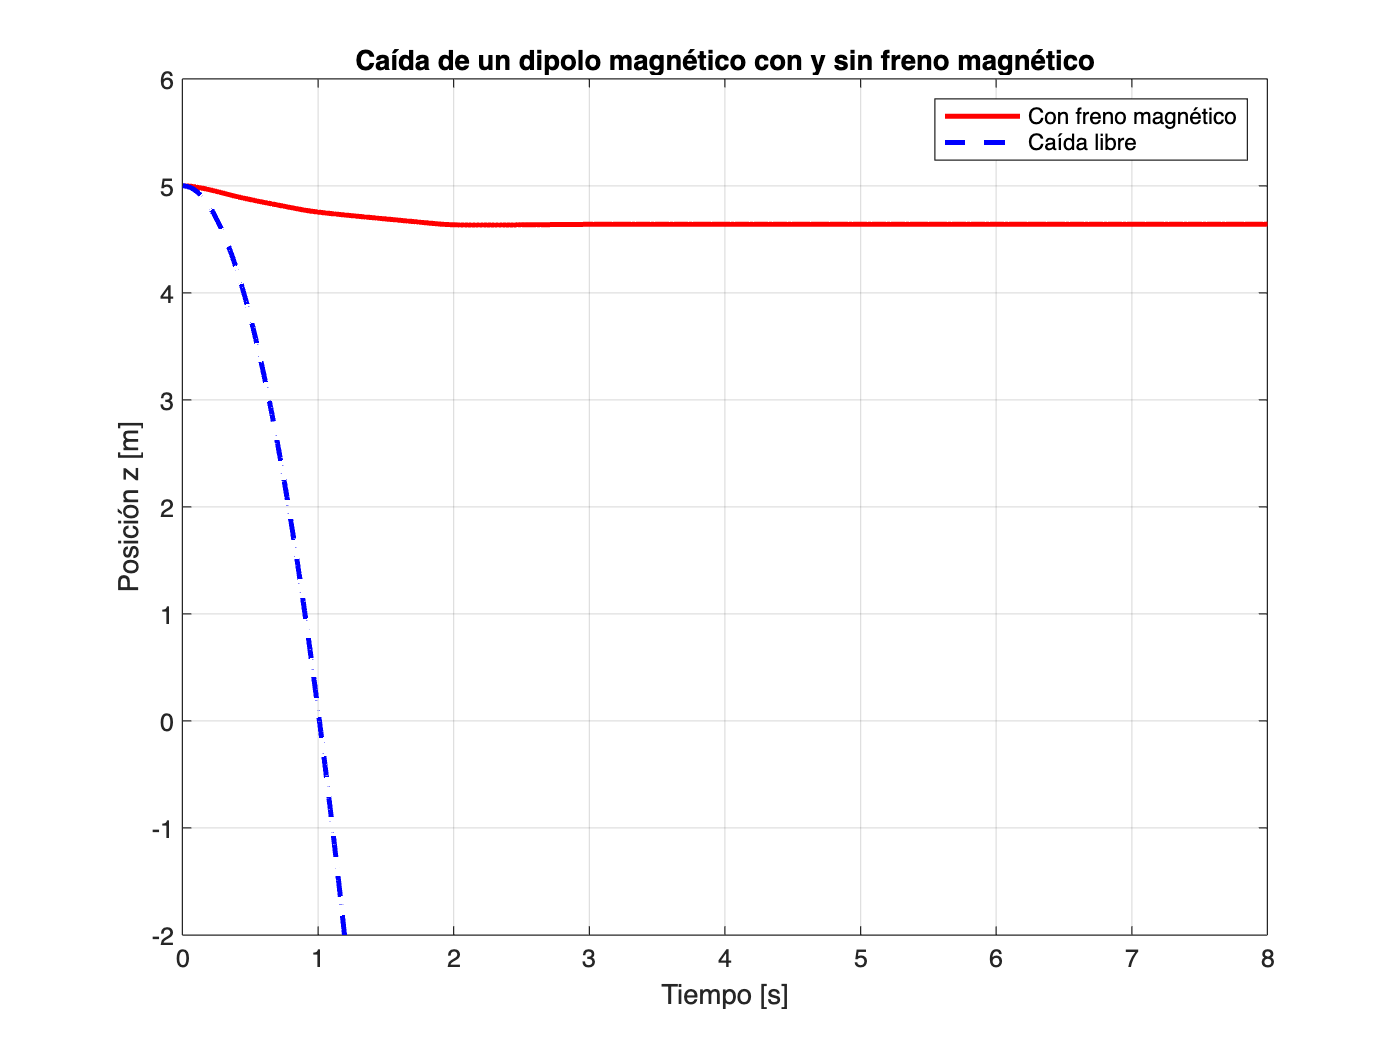

m = 0.009;           % masa [kg]
gamma = 0.08;        % fricción viscosa
mag = 550;           % momento magnético [A·m^2]
g = 9.81;            % gravedad
w = -m * g;          % peso
t_final = 8; dt = 0.01;
t = 0:dt:t_final;
Nt = length(t);

function a = compute_acceleration(z_eval, v_eval, z_grid, Bz_central, z_interp, delta, mag, gamma, w, m)
    z_eval = max(min(z_eval, max(z_interp) - delta), min(z_interp) + delta);
    Bz_fwd = interp1(z_grid, Bz_central, z_eval + delta, 'linear', 'extrap');
    Bz_bwd = interp1(z_grid, Bz_central, z_eval - delta, 'linear', 'extrap');
    dBz_dz = (Bz_fwd - Bz_bwd) / (2 * delta);
    Fm = -mag * dBz_dz;
    Ff = -gamma * v_eval;
    F_total = Fm + Ff + w;
    a = F_total / m;
end

function [z_next, v_next] = rk4_step(z, v, dt, a_func)
    k1z = v;
    k1v = a_func(z, v);

    k2z = v + 0.5 * dt * k1v;
    k2v = a_func(z + 0.5 * dt * k1z, v + 0.5 * dt * k1v);

    k3z = v + 0.5 * dt * k2v;
    k3v = a_func(z + 0.5 * dt * k2z, v + 0.5 * dt * k2v);

    k4z = v + dt * k3v;
    k4v = a_func(z + dt * k3z, v + dt * k3v);

    z_next = z + (dt / 6) * (k1z + 2*k2z + 2*k3z + k4z);
    v_next = v + (dt / 6) * (k1v + 2*k2v + 2*k3v + k4v);
end

vz_mag = zeros(1, Nt);
z_mag = zeros(1, Nt);
vz_libre = zeros(1, Nt);
z_libre = zeros(1, Nt);
z_mag(1) = 5; z_libre(1) = 5;
vz_mag(1) = 0;

idx_x = ceil(lx / 2);
Bz_central = squeeze(Bz(:, idx_x));
Bz_central = Bz_central(:);
z_grid = z(:);

if length(z_grid) ~= length(Bz_central)
    error('z y Bz_central deben tener la misma longitud');
end

delta = 0.005;
a_func = @(z_eval, v_eval) compute_acceleration(z_eval, v_eval, z_grid, Bz_central, z_grid, delta, mag, gamma, w, m);

Fm = zeros(1, Nt);
F = zeros(1, Nt);

for cc = 2:Nt
    z_prev = z_mag(cc-1);
    v_prev = vz_mag(cc-1);

    if z_prev <= min(z_grid)
        z_mag(cc:end) = min(z_grid);
        vz_mag(cc:end) = 0;
        break;
    elseif z_prev >= max(z_grid)
        z_prev = max(z_grid) - delta;
    end

    [z_new, v_new] = rk4_step(z_prev, v_prev, dt, a_func);
    z_mag(cc) = z_new;
    vz_mag(cc) = v_new;

    z_eval = max(min(z_new, max(z_grid) - delta), min(z_grid) + delta);
    Bz_fwd = interp1(z_grid, Bz_central, z_eval + delta, 'linear', 'extrap');
    Bz_bwd = interp1(z_grid, Bz_central, z_eval - delta, 'linear', 'extrap');
    dBz_dz = (Bz_fwd - Bz_bwd) / (2 * delta);
    Fm(cc) = -mag * dBz_dz;
    Ff = -gamma * v_new;
    F(cc) = Fm(cc) + Ff + w;

    % Caída libre
    vz_libre(cc) = vz_libre(cc-1) - g * dt;
    z_libre(cc) = z_libre(cc-1) + vz_libre(cc-1) * dt + 0.5 * (-g) * dt^2;
end

t = t(1:cc);
z_mag = z_mag(1:cc);
z_libre = z_libre(1:cc);
Fm = Fm(1:cc);
F = F(1:cc);

figure;
plot(t, z_mag, 'r', 'LineWidth', 2); hold on;
plot(t, z_libre, 'b--', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('Posición z [m]');
title('Caída de un dipolo magnético con y sin freno magnético');
legend('Con freno magnético', 'Caída libre');
grid on;
ylim([-2 6]);

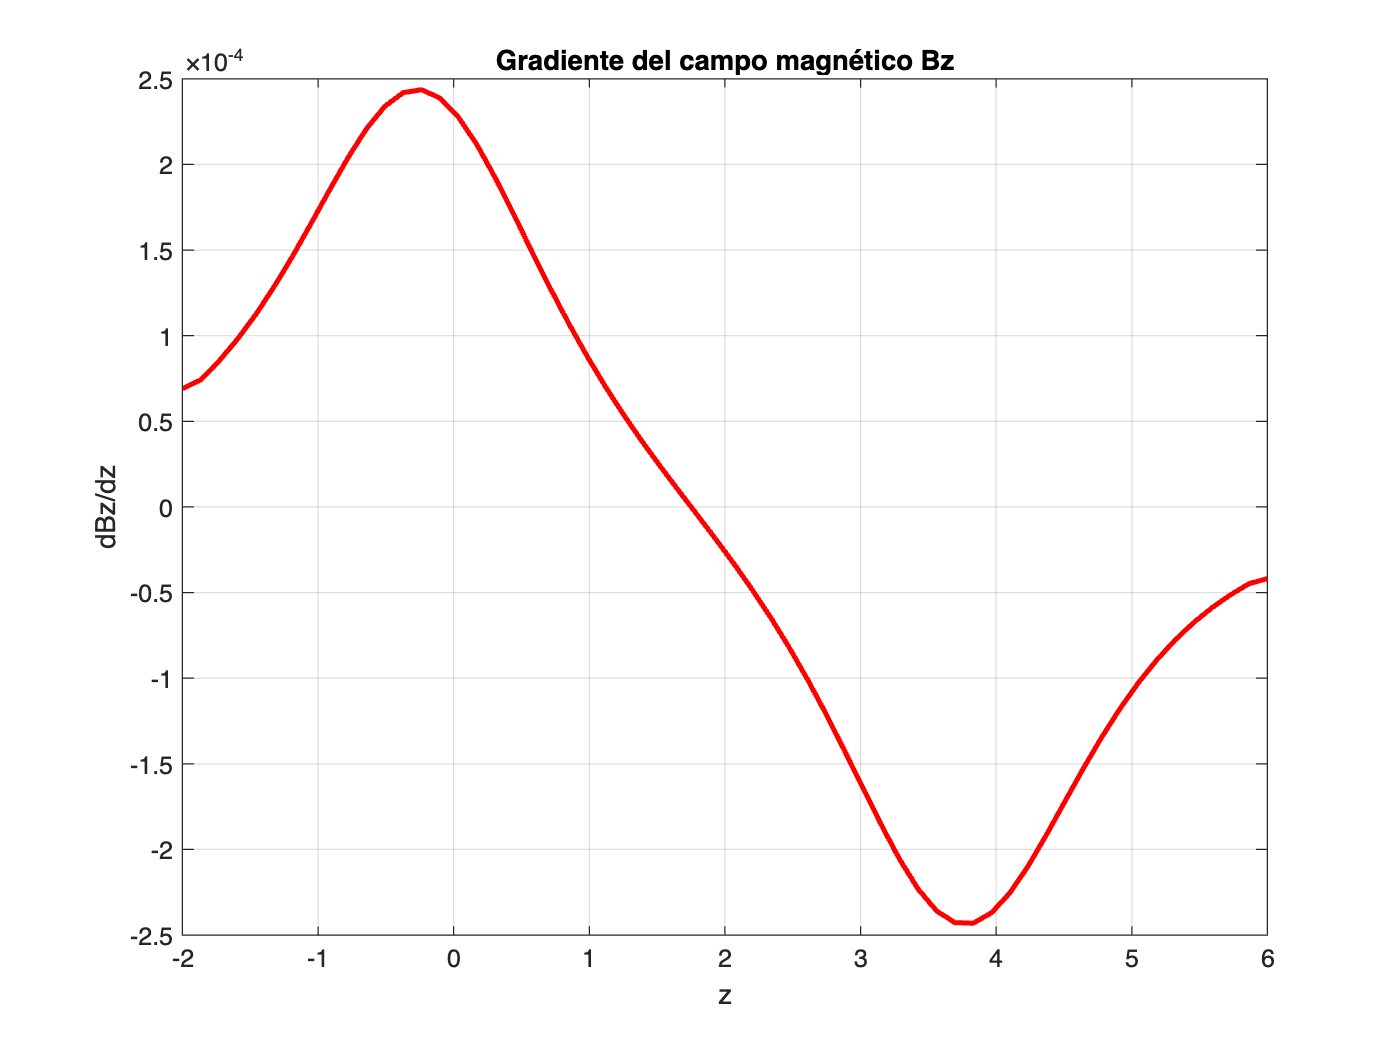

for i = 1:length(z_grid)
    z_fwd = min(z_grid(end), z_grid(i) + delta);
    z_bwd = max(z_grid(1), z_grid(i) - delta);
    Bz_fwd = interp1(z_grid, Bz_central, z_fwd, 'linear', 'extrap');
    Bz_bwd = interp1(z_grid, Bz_central, z_bwd, 'linear', 'extrap');
    dBz_dz_plot(i) = (Bz_fwd - Bz_bwd) / (z_fwd - z_bwd);
end

figure;
plot(z_grid, dBz_dz_plot, 'r', 'LineWidth', 2);
xlabel('z'); ylabel('dBz/dz');
title('Gradiente del campo magnético Bz');
grid on;

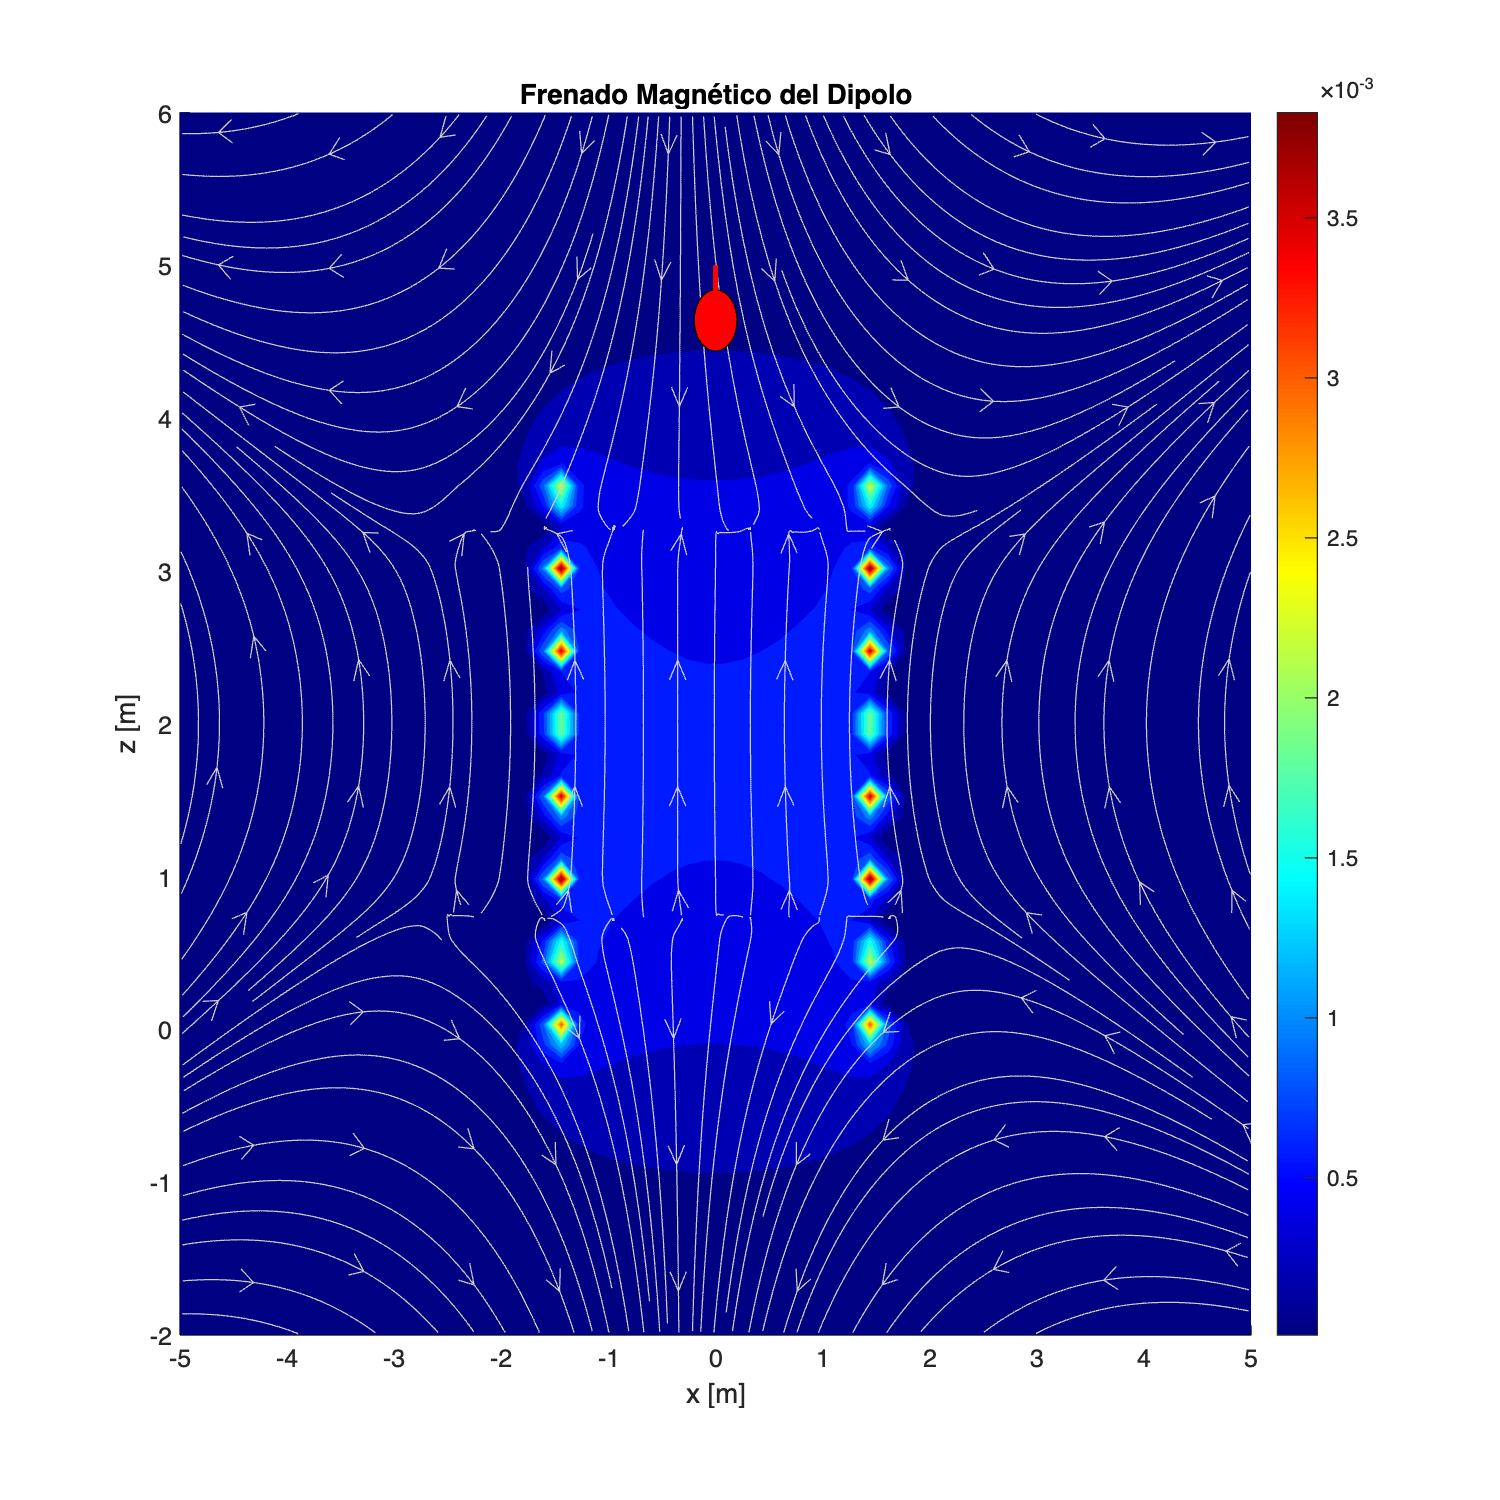

filename = 'dipolo_frenado.gif';

figure('Position', [100, 100, 600, 600]);
hold on;

contourf(x, z, sqrt(Bx.^2 + Bz.^2), 20, 'LineColor', 'none'); 
colormap('jet');
colorbar;
h_stream = streamslice(x, z, Bx', Bz', 2);  
set(h_stream, 'Color', [0.8 0.8 0.8]);

xlabel('x [m]');
ylabel('z [m]');
title('Frenado Magnético del Dipolo');
axis([min(x(:)) max(x(:)) min(z(:)) max(z(:))]);
set(gca, 'Color', 'w');

r_dipolo = 0.2;
theta = linspace(0, 2*pi, 100);
x_circle = r_dipolo * cos(theta);
y_circle = r_dipolo * sin(theta);
h_dipolo = fill(x_circle, y_circle + z_mag(1), 'r');

h_trayectoria = plot(0, z_mag(1), 'r-', 'LineWidth', 2);

for i = 1:3:length(z_mag)
    % Actualiza posición del círculo
    set(h_dipolo, 'YData', y_circle + z_mag(i));
    % Actualiza trayectoria
    set(h_trayectoria, 'XData', zeros(1, i), 'YData', z_mag(1:i));

    drawnow;

    frame = getframe(gcf);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    if i == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.01);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.01);
    end
end